# Laborator 3

## Problema 1

### a)

A = [
    10, 7, 8,  7; 
    7,  5, 6,  5; 
    8,  6, 10, 9; 
    7,  5, 9   10
];
b = [32; 23; 33; 31];
x = A \ b

x =     1.0000
    1.0000
    1.0000
    1.0000


b_perturbat = [32.1; 22.9; 33.1; 30.9];
x_b_perturbat = A \ b_perturbat

x_b_perturbat =     9.2000
  -12.6000
    4.5000
   -1.1000


Eroarea relativa la intrare

relative_input_error_1 = norm(b_perturbat - b) / norm(b) % folosind norma euclidiana

relative_input_error_1 = 0.0033

Eroarea la iesire

relative_output_error_1 = norm(x_b_perturbat - x) / norm(x)

relative_output_error_1 = 8.1985

Raportul lor

fprintf("%.15f\n", relative_output_error_1 / relative_input_error_1);

2460.567236431425954


### b)

A_perturbat = [
    10,   7,    8.1,  7.2;
    7.08, 5.04, 6,    5;
    8,    5.98, 9.89, 9;
    6.99, 4.99, 9,    9.98;
]

A_perturbat =    10.0000    7.0000    8.1000    7.2000
    7.0800    5.0400    6.0000    5.0000
    8.0000    5.9800    9.8900    9.0000
    6.9900    4.9900    9.0000    9.9800


x_A_perturbat = A_perturbat \ b

x_A_perturbat =   -81.0000
  137.0000
  -34.0000
   22.0000


Eroarea relativa la intrare

relative_input_error_2 = norm(A_perturbat - A) / norm(A) % folosind norma euclidiana

relative_input_error_2 = 0.0076

Eroarea la iesire

relative_output_error_2 = norm(x_A_perturbat - x) / norm(x)

relative_output_error_2 = 81.9848

Raportul lor

fprintf("%.15f\n", relative_output_error_2 / relative_input_error_2);

10757.882994722365765


**Fenomen**: perturbari mici in input (intai in b, apoi in A), ce se pot observa din erorile relative de intrare, duc la perturbari mari in output, ce se pot observa din erorile relative din iesire.

**Explicatie**: operatii cu numere reale in floating-point pot provoca modificari majore din cauza rotunjirilor facute, chiar daca modificarile par a fi mici la intrare, pentru ca intr-o functie se pot face multe operatii, ce duc la multe rotunjiri si eliminari de decimale

## Problema 2

Matricea Vandermonde

$V = (v_{ij}), v_{ij} = t_{j}^{i - 1}$, 

i, j = 1,..n

ridicari la putere a coloanelor anterioare

Norma Chebyshev: $||A||_{\infty} = max_i\sum_{j=1}^{n}|a_{ij}|$, sau, maximul dupa linii a sumelor in modul a tuturor elementelor de pe coloane

cond(A) = $||A|| \times ||A^{-1}||$, nr de conditionare, daca e nesingulara (inverabila)

a) $t_{k} = -1 + k * \frac{2}{n}, k = \overline{1,n}$ - genereaza puncte echidistante in [-1, 1]

n_values = 10:15;   

for n = n_values
    tk = -1 + (1 : n) * (2 / n);
    
    Vn = zeros(n); % matricea Vandermonde
    for i = 1:n
        Vn(:, i) = tk .^ (i - 1);
    end
    Vn

    if det(Vn) == 0
        disp('Matrix is singular, cannot invert.');
    else
        inverse_Vn = inv(Vn);
    end

    cond_number = norm(Vn, inf) * norm(inverse_Vn, inf); % in matlab functia norm() cu al 2-lea param = inf, utilizeaza norma chebyshev / maximum absolute sums
    
    fprintf('n = %d, Condition Number (Chebyshev Norm): %f\n', n, cond_number);
end

Vn =     1.0000   -0.8000    0.6400   -0.5120    0.4096   -0.3277    0.2621   -0.2097    0.1678   -0.1342
    1.0000   -0.6000    0.3600   -0.2160    0.1296   -0.0778    0.0467   -0.0280    0.0168   -0.0101
    1.0000   -0.4000    0.1600   -0.0640    0.0256   -0.0102    0.0041   -0.0016    0.0007   -0.0003
    1.0000   -0.2000    0.0400   -0.0080    0.0016   -0.0003    0.0001   -0.0000    0.0000   -0.0000
    1.0000         0         0         0         0         0         0         0         0         0
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000
    1.0000    0.4000    0.1600    0.0640    0.0256    0.0102    0.0041    0.0016    0.0007    0.0003
    1.0000    0.6000    0.3600    0.2160    0.1296    0.0778    0.0467    0.0280    0.0168    0.0101
    1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.

n = 10, Condition Number (Chebyshev Norm): 33094.618056


Vn =     1.0000   -0.8182    0.6694   -0.5477    0.4481   -0.3666    0.3000   -0.2454    0.2008   -0.1643    0.1344
    1.0000   -0.6364    0.4050   -0.2577    0.1640   -0.1044    0.0664   -0.0423    0.0269   -0.0171    0.0109
    1.0000   -0.4545    0.2066   -0.0939    0.0427   -0.0194    0.0088   -0.0040    0.0018   -0.0008    0.0004
    1.0000   -0.2727    0.0744   -0.0203    0.0055   -0.0015    0.0004   -0.0001    0.0000   -0.0000    0.0000
    1.0000   -0.0909    0.0083   -0.0008    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000    0.0909    0.0083    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2727    0.0744    0.0203    0.0055    0.0015    0.0004    0.0001    0.0000    0.0000    0.0000
    1.0000    0.4545    0.2066    0.0939    0.0427    0.0194    0.0088    0.0040    0.0018    0.0008    0.0004
    1.0000    0.6364    0.4050    0.2577    0.1640    0.1044    0.0664    0.0423    0.0269    0.0171    0.0

n = 11, Condition Number (Chebyshev Norm): 107233.920170


Vn =     1.0000   -0.8333    0.6944   -0.5787    0.4823   -0.4019    0.3349   -0.2791    0.2326   -0.1938    0.1615   -0.1346
    1.0000   -0.6667    0.4444   -0.2963    0.1975   -0.1317    0.0878   -0.0585    0.0390   -0.0260    0.0173   -0.0116
    1.0000   -0.5000    0.2500   -0.1250    0.0625   -0.0312    0.0156   -0.0078    0.0039   -0.0020    0.0010   -0.0005
    1.0000   -0.3333    0.1111   -0.0370    0.0123   -0.0041    0.0014   -0.0005    0.0002   -0.0001    0.0000   -0.0000
    1.0000   -0.1667    0.0278   -0.0046    0.0008   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    1.0000         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000
    1.0000    0.5000    0.2

n = 12, Condition Number (Chebyshev Norm): 341255.314286


Vn =     1.0000   -0.8462    0.7160   -0.6058    0.5126   -0.4338    0.3670   -0.3106    0.2628   -0.2224    0.1881   -0.1592    0.1347
    1.0000   -0.6923    0.4793   -0.3318    0.2297   -0.1590    0.1101   -0.0762    0.0528   -0.0365    0.0253   -0.0175    0.0121
    1.0000   -0.5385    0.2899   -0.1561    0.0841   -0.0453    0.0244   -0.0131    0.0071   -0.0038    0.0020   -0.0011    0.0006
    1.0000   -0.3846    0.1479   -0.0569    0.0219   -0.0084    0.0032   -0.0012    0.0005   -0.0002    0.0001   -0.0000    0.0000
    1.0000   -0.2308    0.0533   -0.0123    0.0028   -0.0007    0.0002   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.0769    0.0059   -0.0005    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000    0.0769    0.0059    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2308    0.0533    0.0123    0.0028    0.0007    0.0002    0.00

n = 13, Condition Number (Chebyshev Norm): 1070054.615049


Vn =     1.0000   -0.8571    0.7347   -0.6297    0.5398   -0.4627    0.3966   -0.3399    0.2914   -0.2497    0.2141   -0.1835    0.1573   -0.1348
    1.0000   -0.7143    0.5102   -0.3644    0.2603   -0.1859    0.1328   -0.0949    0.0678   -0.0484    0.0346   -0.0247    0.0176   -0.0126
    1.0000   -0.5714    0.3265   -0.1866    0.1066   -0.0609    0.0348   -0.0199    0.0114   -0.0065    0.0037   -0.0021    0.0012   -0.0007
    1.0000   -0.4286    0.1837   -0.0787    0.0337   -0.0145    0.0062   -0.0027    0.0011   -0.0005    0.0002   -0.0001    0.0000   -0.0000
    1.0000   -0.2857    0.0816   -0.0233    0.0067   -0.0019    0.0005   -0.0002    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    1.0000   -0.1429    0.0204   -0.0029    0.0004   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.00

n = 14, Condition Number (Chebyshev Norm): 3314038.087765


Vn =     1.0000   -0.8667    0.7511   -0.6510    0.5642   -0.4889    0.4238   -0.3673    0.3183   -0.2758    0.2391   -0.2072    0.1796   -0.1556    0.1349
    1.0000   -0.7333    0.5378   -0.3944    0.2892   -0.2121    0.1555   -0.1141    0.0836   -0.0613    0.0450   -0.0330    0.0242   -0.0177    0.0130
    1.0000   -0.6000    0.3600   -0.2160    0.1296   -0.0778    0.0467   -0.0280    0.0168   -0.0101    0.0060   -0.0036    0.0022   -0.0013    0.0008
    1.0000   -0.4667    0.2178   -0.1016    0.0474   -0.0221    0.0103   -0.0048    0.0022   -0.0010    0.0005   -0.0002    0.0001   -0.0000    0.0000
    1.0000   -0.3333    0.1111   -0.0370    0.0123   -0.0041    0.0014   -0.0005    0.0002   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.2000    0.0400   -0.0080    0.0016   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.0667    0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.000

n = 15, Condition Number (Chebyshev Norm): 10157560.373344


b) $t_k = \frac{1}{k}, k = \overline{1,n}$

n_values = 10:15;

for n = n_values
    tk = 1 ./ (1 : n);
    
    Vn = zeros(n);
    for i = 1:n
        Vn(:, i) = tk .^ (i - 1);
    end
    Vn

    if det(Vn) == 0
        disp('Matrix is singular, cannot invert.');
    else
        inverse_Vn = inv(Vn);
    end

    cond_number = norm(Vn, inf) * norm(inverse_Vn, inf);
    
    fprintf('n = %d, Condition Number (Chebyshev Norm): %f\n', n, cond_number);
end

Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1250    0.0156    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1111    0.0123    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.

n = 10, Condition Number (Chebyshev Norm): 579241798023.140625


Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1250    0.0156    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1111    0.0123    0.0014    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

n = 11, Condition Number (Chebyshev Norm): 23824314904517.500000


Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1250    0.0156    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1111    0.0

n = 12, Condition Number (Chebyshev Norm): 1058853861065759.750000


Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1250    0.0156    0.0020    0.0002    0.0000    0.0000    0.00

n = 13, Condition Number (Chebyshev Norm): 51109954936116352.000000


Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.00

n = 14, Condition Number (Chebyshev Norm): 763132304349467008.000000


Vn =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001
    1.0000    0.3333    0.1111    0.0370    0.0123    0.0041    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2000    0.0400    0.0080    0.0016    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1667    0.0278    0.0046    0.0008    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1429    0.0204    0.0029    0.0004    0.0001    0.0000    0.0000    0.000

n = 15, Condition Number (Chebyshev Norm): 773427206111986304.000000


## Problema 3

formula pt nr de conditionare $\kappa = \frac{max_i\left|\frac{\Delta x_i}{x_i}\right|}{max_j\left|\frac{\Delta a_j}{a_j}\right|}= \frac{relative\_output\_error}{relative\_input\_error}$

1) ecuatia $(x - 1)(x - 2)...(x-n) = 0$ => combinari

n = 20;
coeffs = zeros(1, n+1);
    
% pt fiecare coeficient
for i = 0:n
    coeff_i = 0; % coeficientul curent pe care il calculam
    %fprintf("i = %d\n", i);
    % combinarile de la 1 la n, luate de cate n-i fiecare
    for comb = nchoosek(1 : n, n - i)'
        % adaugam la coeficientul curent produsul lor * -1
        coeff_i = coeff_i + prod(-comb);
    end
    coeffs(i + 1) = coeff_i;
end
% flip ca sa ii avem in ordine pt functia roots()
coeffs = flip(coeffs);
for i = 1:length(coeffs)
    fprintf("a_%d = %f\n", i - 1, coeffs(i))
end

a_0 = 1.000000
a_1 = -210.000000
a_2 = 20615.000000
a_3 = -1256850.000000
a_4 = 53327946.000000
a_5 = -1672280820.000000
a_6 = 40171771630.000000
a_7 = -756111184500.000000
a_8 = 11310276995381.000000
a_9 = -135585182899530.000000
a_10 = 1307535010540395.000000
a_11 = -10142299865511450.000000
a_12 = 63030812099294896.000000
a_13 = -311333643161390656.000000
a_14 = 1206647803780373504.000000
a_15 = -3599979517947607040.000000
a_16 = 8037811822645052416.000000
a_17 = -12870931245150988288.000000
a_18 = 13803759753640704000.000000
a_19 = -8752948036761600000.000000
a_20 = 2432902008176640000.000000


no_iters = 100;

initial_coeffs = coeffs;
initial_roots = roots(coeffs);

mu = 0;
variance = 10^(-10);

condition_numbers = zeros(length(coeffs) - 1, no_iters);

for i = 1:no_iters
    new_coeffs = perturbateCoefficients(initial_coeffs, mu, variance);
    relative_input_changes = abs((new_coeffs - initial_coeffs) ./ initial_coeffs);
    new_roots = roots(new_coeffs);
    relative_output_changes = abs((new_roots - initial_roots) ./ initial_roots);
    
    % test new coeffs pt valori largi
    if i == 1
        for z = 1:length(new_coeffs)
            fprintf("a_%d = %.20f\n", z - 1, new_coeffs(z))
        end
    end

    % calculez nr de conditionare pt fiecare radacina, la iteratia i
    for j = 1:length(coeffs) - 1
        condition_numbers(j, i) = max([ ...
            condition_numbers(j, i), ...
            relative_output_changes(j) / relative_input_changes(j) ...
        ]);
    end
end

a_0 = 0.99998446199208845808
a_1 = -210.00000354291623239078
a_2 = 20615.00000434227695222944
a_3 = -1256850.00000101467594504356
a_4 = 53327946.00002028793096542358
a_5 = -1672280820.00000357627868652344
a_6 = 40171771629.99997711181640625000
a_7 = -756111184500.00000000000000000000
a_8 = 11310276995381.00000000000000000000
a_9 = -135585182899530.00000000000000000000
a_10 = 1307535010540395.00000000000000000000
a_11 = -10142299865511450.00000000000000000000
a_12 = 63030812099294896.00000000000000000000
a_13 = -311333643161390656.00000000000000000000
a_14 = 1206647803780373504.00000000000000000000
a_15 = -3599979517947607040.00000000000000000000
a_16 = 8037811822645052416.00000000000000000000
a_17 = -12870931245150988288.00000000000000000000
a_18 = 13803759753640704000.00000000000000000000
a_19 = -8752948036761600000.00000000000000000000
a_20 = 2432902008176640000.00000000000000000000


condition_numbers

condition_numbers = 	1.0e+15 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

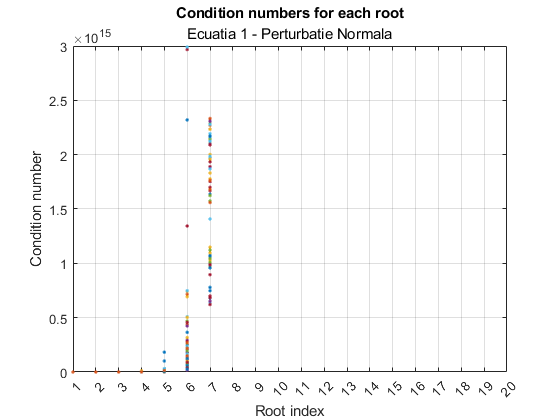

% plotting
figure;
plot(1:length(coeffs)-1, condition_numbers, '.');
xlabel('Root index');
ylabel('Condition number');
title('Condition numbers for each root');
subtitle('Ecuatia 1 - Perturbatie Normala');
grid on;
xticks(1:length(coeffs)-1);
xlim([1, length(coeffs)-1]);
saveas(gcf, 'ec1_normal_plot.png');

2) ecuatia $a_0x^n + a_1x^{n - 1} + a_2x^{n-2}+... + a_n = 0$


$$a_k = 2^{-k}, k = \overline{0,n}$$


clear
k = 0:20;
initial_coeffs = 2.^(-k)

initial_coeffs =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


for i = 1:length(initial_coeffs)
    fprintf("a_%d = %.15f\n", i, initial_coeffs(i))
end

a_1 = 1.000000000000000
a_2 = 0.500000000000000
a_3 = 0.250000000000000
a_4 = 0.125000000000000
a_5 = 0.062500000000000
a_6 = 0.031250000000000
a_7 = 0.015625000000000
a_8 = 0.007812500000000
a_9 = 0.003906250000000
a_10 = 0.001953125000000
a_11 = 0.000976562500000
a_12 = 0.000488281250000
a_13 = 0.000244140625000
a_14 = 0.000122070312500
a_15 = 0.000061035156250
a_16 = 0.000030517578125
a_17 = 0.000015258789062
a_18 = 0.000007629394531
a_19 = 0.000003814697266
a_20 = 0.000001907348633
a_21 = 0.000000953674316


initial_roots = roots(initial_coeffs)

initial_roots =    0.4778 + 0.1474i
   0.4778 - 0.1474i
   0.4131 + 0.2817i
   0.4131 - 0.2817i
   0.3117 + 0.3909i
   0.3117 - 0.3909i
  -0.4944 + 0.0745i
  -0.4944 - 0.0745i
  -0.4505 + 0.2169i
  -0.4505 - 0.2169i


no_iters = 100;

mu = 0;
variance = 10^(-10);

condition_numbers = zeros(length(initial_coeffs) - 1, no_iters);

for i = 1:no_iters
    new_coeffs = perturbateCoefficients(initial_coeffs, mu, variance);
    relative_input_changes = abs((new_coeffs - initial_coeffs) ./ initial_coeffs);
    new_roots = roots(new_coeffs);
    relative_output_changes = abs((new_roots - initial_roots) ./ initial_roots);
    
    % test new coeffs pt valori largi
    if i == 1
        for z = 1:length(new_coeffs)
            fprintf("a_%d = %.20f\n", z - 1, new_coeffs(z))
        end
    end

    % calculez nr de conditionare pt fiecare radacina, la iteratia i
    for j = 1:length(initial_coeffs) - 1
        condition_numbers(j, i) = max([ ...
            condition_numbers(j, i), ...
            relative_output_changes(j) / relative_input_changes(j) ...
        ]);
    end
end

a_0 = 1.00000294179209081591
a_1 = 0.50001151372070140599
a_2 = 0.24999139734689262982
a_3 = 0.12499943904880411738
a_4 = 0.06248785252955389724
a_5 = 0.03124068896493876341
a_6 = 0.01561052713502512901
a_7 = 0.00780315250950475072
a_8 = 0.00390992631234717784
a_9 = 0.00195072348886893461
a_10 = 0.00098239289619924362
a_11 = 0.00049855864957895548
a_12 = 0.00024776619395300428
a_13 = 0.00012982512259928486
a_14 = 0.00006858497361879131
a_15 = 0.00005409076279334864
a_16 = 0.00002283083319292286
a_17 = -0.00000729059306541129
a_18 = 0.00000677238287257040
a_19 = 0.00000858144984827856
a_20 = 0.00001038023453971515


% coloana i = iteratia i
condition_numbers

condition_numbers = 	1.0e+07 *

    0.0030    0.0018    0.0031    0.0065    0.0213    0.0343    0.0205    0.0017    0.0289    0.0616    0.0005    0.0007    0.0433    0.4696    0.0129    0.0355    0.0188    0.2907    0.9711    0.0014    0.0124    0.0217    0.0780    0.0016    0.0559    0.0004    0.0768    0.0133    0.0093    0.0448    0.0018    0.0156    0.0026    0.0667    0.0005    0.0107    0.0183    0.0101    0.0070    0.0141    0.0023    0.0342    0.0033    0.0388    0.0120    0.0086    0.0007    0.6252    0.0220    0.0602
    0.0004    0.0015    0.0039    0.0001    0.0281    0.0266    0.0437    0.0021    0.0331    0.0450    0.0008    0.0003    0.0280    0.0064    0.2905    0.0185    0.0344    0.0101    0.0118    0.0004    0.0005    0.0066    0.0142    0.0016    0.0613    0.0008    0.0245    0.0205    0.0005    0.0193    0.0004    2.3249    0.0005    0.0074    0.0005    0.0062    0.0120    0.0549    0.0017    0.0300    0.0009    0.0078    0.0004    0.0079    0.0059    0.0062    0.0

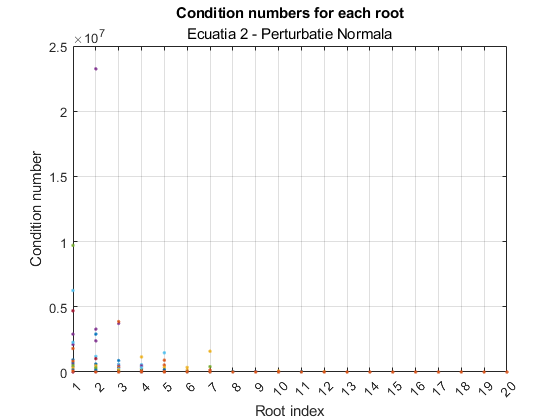

% plotting
figure;
plot(1:length(initial_coeffs)-1, condition_numbers, '.');
xlabel('Root index');
ylabel('Condition number');
title('Condition numbers for each root');
subtitle('Ecuatia 2 - Perturbatie Normala')
grid on;
xticks(1:length(initial_coeffs)-1);
xlim([1, length(initial_coeffs)-1]);
saveas(gcf, 'ec2_normal_plot.png');

Folosind distributia uniforma

cu media si varianta


$$f(x) = 
\begin{cases}
    \frac{1}{2\sigma\sqrt{3}}, for \ -\sigma\sqrt{3} \leq x - \mu \leq \sigma\sqrt{3} \\
    0,otherwise
\end{cases}
$$


1)

n = 20;
coeffs = zeros(1, n+1);
    
% pt fiecare coeficient
for i = 0:n
    coeff_i = 0; % coeficientul curent pe care il calculam
    %fprintf("i = %d\n", i);
    % combinarile de la 1 la n, luate de cate n-i fiecare
    for comb = nchoosek(1 : n, n - i)'
        % adaugam la coeficientul curent produsul lor * -1
        coeff_i = coeff_i + prod(-comb);
    end
    coeffs(i + 1) = coeff_i;
end
% flip ca sa ii avem in ordine pt functia roots()
coeffs = flip(coeffs);
for i = 1:length(coeffs)
    fprintf("a_%d = %f\n", i - 1, coeffs(i))
end

a_0 = 1.000000
a_1 = -210.000000
a_2 = 20615.000000
a_3 = -1256850.000000
a_4 = 53327946.000000
a_5 = -1672280820.000000
a_6 = 40171771630.000000
a_7 = -756111184500.000000
a_8 = 11310276995381.000000
a_9 = -135585182899530.000000
a_10 = 1307535010540395.000000
a_11 = -10142299865511450.000000
a_12 = 63030812099294896.000000
a_13 = -311333643161390656.000000
a_14 = 1206647803780373504.000000
a_15 = -3599979517947607040.000000
a_16 = 8037811822645052416.000000
a_17 = -12870931245150988288.000000
a_18 = 13803759753640704000.000000
a_19 = -8752948036761600000.000000
a_20 = 2432902008176640000.000000


no_iters = 100;

initial_coeffs = coeffs;
initial_roots = roots(coeffs);

mu = 0;
variance = 10^(-10);

condition_numbers = zeros(length(coeffs) - 1, no_iters);
max_relative_input_changes = zeros(no_iters, 1);
max_relative_output_changes = zeros(no_iters, 1);

for i = 1:no_iters
    new_coeffs = perturbateCoefficientsUniform(initial_coeffs, mu, variance);
    relative_input_changes = abs((new_coeffs - initial_coeffs) ./ initial_coeffs);
    new_roots = roots(new_coeffs);
    relative_output_changes = abs((new_roots - initial_roots) ./ initial_roots);
    
    % test new coeffs pt valori largi
    if i == 1
        for z = 1:length(new_coeffs)
            fprintf("a_%d = %.20f\n", z - 1, new_coeffs(z))
        end
    end

    % calculez nr de conditionare pt fiecare radacina, la iteratia i
    for j = 1:length(coeffs) - 1
        condition_numbers(j, i) = max([ ...
            condition_numbers(j, i), ...
            relative_output_changes(j) / relative_input_changes(j) ...
        ]);
    end
end

a_0 = 1.00001636823826123290
a_1 = -210.00000741305152018867
a_2 = 20615.00000343029023497365
a_3 = -1256849.99998779920861124992
a_4 = 53327945.99999115616083145142
a_5 = -1672280819.99999213218688964844
a_6 = 40171771630.00000000000000000000
a_7 = -756111184500.00000000000000000000
a_8 = 11310276995381.00000000000000000000
a_9 = -135585182899530.00000000000000000000
a_10 = 1307535010540395.00000000000000000000
a_11 = -10142299865511450.00000000000000000000
a_12 = 63030812099294896.00000000000000000000
a_13 = -311333643161390656.00000000000000000000
a_14 = 1206647803780373504.00000000000000000000
a_15 = -3599979517947607040.00000000000000000000
a_16 = 8037811822645052416.00000000000000000000
a_17 = -12870931245150988288.00000000000000000000
a_18 = 13803759753640704000.00000000000000000000
a_19 = -8752948036761600000.00000000000000000000
a_20 = 2432902008176640000.00000000000000000000


condition_numbers

condition_numbers = 	1.0e+15 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

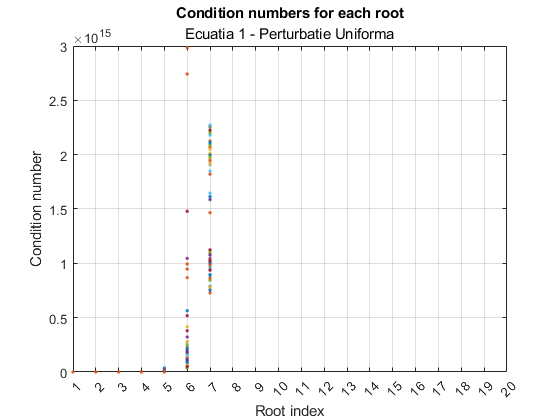

% plotting
figure;
plot(1:length(coeffs)-1, condition_numbers, '.');
xlabel('Root index');
ylabel('Condition number');
title('Condition numbers for each root');
subtitle('Ecuatia 1 - Perturbatie Uniforma');
grid on;
xticks(1:length(coeffs)-1);
xlim([1, length(coeffs)-1]);
saveas(gcf, 'ec1_uniform_plot.png');

2)

clear
k = 0:20;
initial_coeffs = 2.^(-k)

initial_coeffs =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


for i = 1:length(initial_coeffs)
    fprintf("a_%d = %.15f\n", i, initial_coeffs(i))
end

a_1 = 1.000000000000000
a_2 = 0.500000000000000
a_3 = 0.250000000000000
a_4 = 0.125000000000000
a_5 = 0.062500000000000
a_6 = 0.031250000000000
a_7 = 0.015625000000000
a_8 = 0.007812500000000
a_9 = 0.003906250000000
a_10 = 0.001953125000000
a_11 = 0.000976562500000
a_12 = 0.000488281250000
a_13 = 0.000244140625000
a_14 = 0.000122070312500
a_15 = 0.000061035156250
a_16 = 0.000030517578125
a_17 = 0.000015258789062
a_18 = 0.000007629394531
a_19 = 0.000003814697266
a_20 = 0.000001907348633
a_21 = 0.000000953674316


initial_roots = roots(initial_coeffs)

initial_roots =    0.4778 + 0.1474i
   0.4778 - 0.1474i
   0.4131 + 0.2817i
   0.4131 - 0.2817i
   0.3117 + 0.3909i
   0.3117 - 0.3909i
  -0.4944 + 0.0745i
  -0.4944 - 0.0745i
  -0.4505 + 0.2169i
  -0.4505 - 0.2169i


no_iters = 100;

mu = 0;
variance = 10^(-10);

condition_numbers = zeros(length(initial_coeffs) - 1, no_iters);

for i = 1:no_iters
    new_coeffs = perturbateCoefficientsUniform(initial_coeffs, mu, variance);
    relative_input_changes = abs((new_coeffs - initial_coeffs) ./ initial_coeffs);
    new_roots = roots(new_coeffs);
    relative_output_changes = abs((new_roots - initial_roots) ./ initial_roots);
    
    % test new coeffs pt valori largi
    if i == 1
        for z = 1:length(new_coeffs)
            fprintf("a_%d = %.20f\n", z - 1, new_coeffs(z))
        end
    end

    % calculez nr de conditionare pt fiecare radacina, la iteratia i
    for j = 1:length(initial_coeffs) - 1
        condition_numbers(j, i) = max([ ...
            condition_numbers(j, i), ...
            relative_output_changes(j) / relative_input_changes(j) ...
        ]);
    end
end

a_0 = 1.00000783554841277123
a_1 = 0.49999751902282935090
a_2 = 0.24998998154294030383
a_3 = 0.12499187267265242374
a_4 = 0.06251708438642991639
a_5 = 0.03124933338108527164
a_6 = 0.01563635359761153185
a_7 = 0.00781607627843381066
a_8 = 0.00391726035880745997
a_9 = 0.00196890561689223647
a_10 = 0.00098177175342606111
a_11 = 0.00049270308378384644
a_12 = 0.00024921772772691230
a_13 = 0.00010690215913885672
a_14 = 0.00007621473333736630
a_15 = 0.00004432952067952786
a_16 = 0.00002200890847296286
a_17 = 0.00000106167164660688
a_18 = -0.00000160504193668749
a_19 = -0.00001277249407202449
a_20 = 0.00000164084609599512


% coloana i = iteratia i
condition_numbers

condition_numbers = 	1.0e+07 *

    0.0268    0.0567    0.0122    0.1014    0.0007    0.0137    0.0204    0.0144    0.0003    0.0384    0.1610    0.0026    0.0241    0.0729    0.0187    0.0019    0.0298    0.0044    0.0146    0.0164    0.0190    0.0007    1.1616    0.0009    0.0324    0.0152    0.0198    0.0202    0.0059    0.0032    0.0006    0.0126    0.0011    0.0358    0.0181    0.0447    0.0012    0.0166    0.0097    0.1221    0.0741    0.2276    0.0017    0.0015    0.0574    0.0013    0.0015    0.1034    0.0179    0.0795
    0.0423    0.0137    0.0137    0.0135    0.0005    0.0277    0.0208    0.0068    0.0006    0.0171    0.4739    0.0019    0.0119    0.0302    0.0068    0.0023    0.0105    0.0024    0.0076    0.0459    0.0015    0.0004    0.0081    0.0002    0.0015    0.0464    0.0070    0.0287    0.0002    0.0005    0.0055    0.0064    0.0039    0.0086    0.0071    0.0063    0.0004    0.0184    0.0003    0.0098    0.0255    0.0753    0.0029    0.0009    0.0134    0.0002    0.0

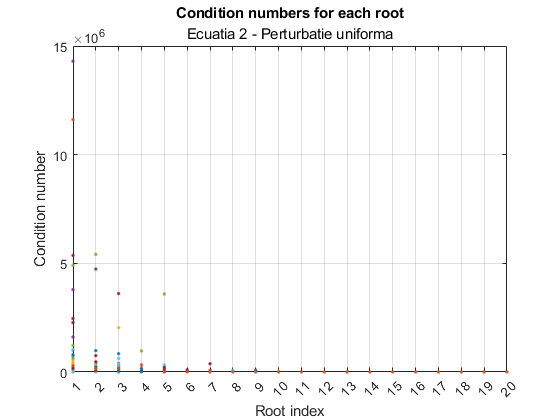

% plotting
figure;
plot(1:length(initial_coeffs)-1, condition_numbers, '.');
xlabel('Root index');
ylabel('Condition number');
title('Condition numbers for each root');
subtitle('Ecuatia 2 - Perturbatie uniforma');
grid on;
xticks(1:length(initial_coeffs)-1);
xlim([1, length(initial_coeffs)-1]);
saveas(gcf, 'ec2_uniform_plot.png');